## Formler

1.1, 1.3, 1.7, 1,12b) og c), 1.12e

### Fourier’s law.

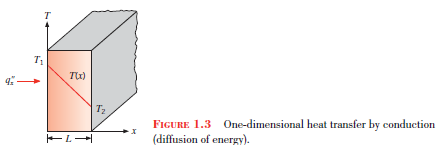

### Newton’s law of cooling

convective heat flux

net rate of radiation heat transfer from the surface

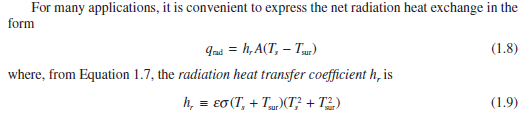

### conservation statement

simplified steady-flow thermal energy equation:

**Opgaver**

**Opgave 1.30**

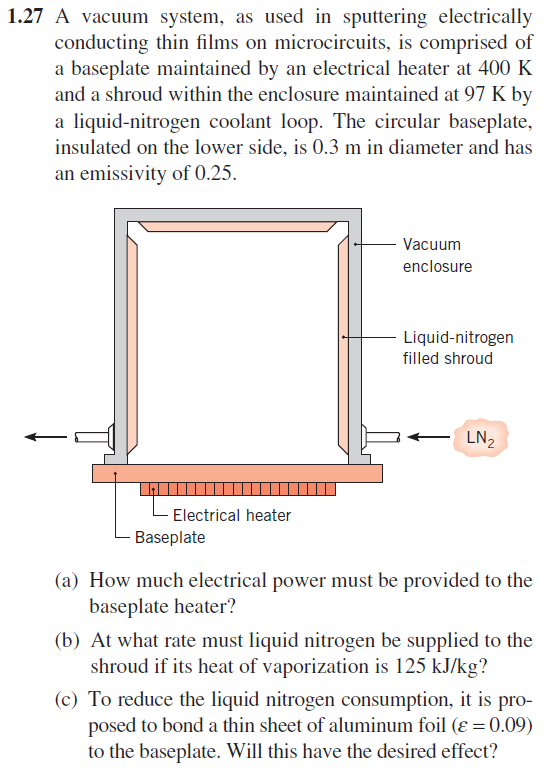

%a
T_heater = 400; %K
T_shroud = 97; %K
d=0.3; %m
epsilon = 0.25; %emesivitet
sigma = 5.67 * 10^-8; % J/K %stefan-boltzman konstant
A = pi*(d/2)^2;
q = A*epsilon * sigma * (T_heater^4 - T_shroud^4)

%b
l_f = 125000 %kJ/kg
%Q = m*L_f
m_dot = q/l_f %masse stræmmen kg/s

m_dot_hours = m_dot * 60 * 60


supplie 0,205 gram per s or 0,7362 kg per time

%c
epsilon_alu = 0.09
q_alu = q * (epsilon_alu/epsilon) % vi tager og divdere q med epsilon og ganger med epsilon alu istedet.

m_dot = q_alu/l_f %masse stræmmen kg/s

m_dot_hours = m_dot * 60 * 60

**Opgave 1.48**

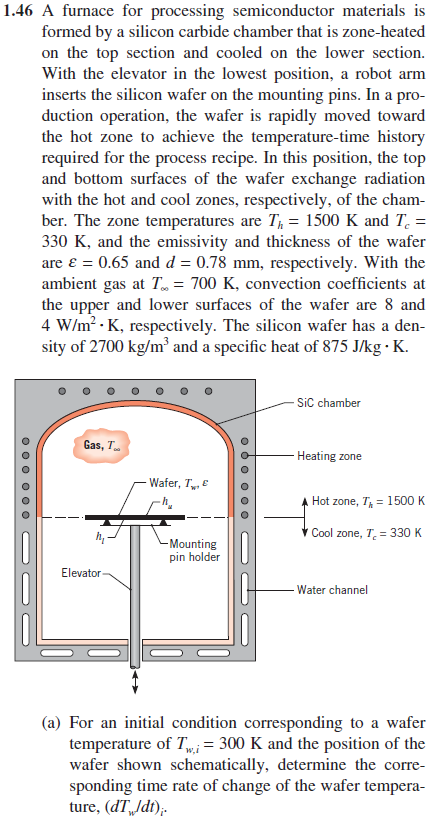

ASSUMPTIONS: 

(1) Wafer temperature is uniform, 

(2) Transient conditions when wafer is initially positioned, 

(3) Hot and cool zones have uniform temperatures, 

(4) Radiation exchange is between small surface (wafer) and large enclosure (chamber, hot or cold zone),

(5) Negligible heat losses from wafer to mounting pin holder.

clear all
T_h = 1500; %K
T_c = 330; %K
epsilon = 0.65; % from wafer
d = 0.78 *1e-3; %thickness of wafer %m
T_amb = 700 %K
sigma = 5.67 * 10^-8; % J/K
h_up = 8 % W/m^2*K
h_low = 4 % W/m^2*K

rho_SiC = 2700; % kg/m^3
c_p =  875; % J/kg*K

T_wi = 300; %K

q_con_h = h_up * (T_wi - T_amb) %convection above plate
q_con_l = h_low * (T_wi- T_amb) %convection below plate
q_rad_h = epsilon * sigma * (T_h^4 - T_wi^4) %radiation above plate
q_rad_l = epsilon * sigma * (T_c^4 - T_wi^4) %radiation below plate

q_mark = - q_con_h - q_con_l + q_rad_h + q_rad_l
dTdt = q_mark / (rho_SiC * c_p * d)
vpa(dTdt, 4)

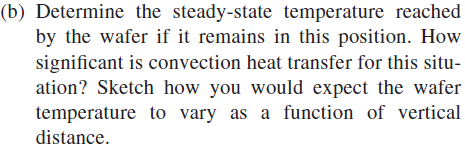

syms T_wi
q_con_h = h_up * (T_wi - T_amb); %convection above plate
q_con_l = h_low * (T_wi- T_amb); %convection below plate
q_rad_h = epsilon * sigma * (T_h^4 - T_wi^4); %radiation above plate
q_rad_l = epsilon * sigma * (T_c^4 - T_wi^4); %radiation below plate
q_mark = - q_con_h - q_con_l + q_rad_h + q_rad_l;
dTdt_eq = 0 == q_mark / (rho_SiC * c_p * d);

T_wi_steady = vpa(solve(dTdt_eq, T_wi),5)

Her bruger vi den reele løsning der er positiv 1251 K

## Figurer

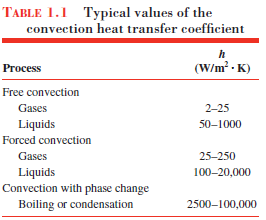

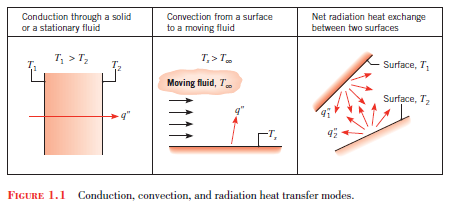

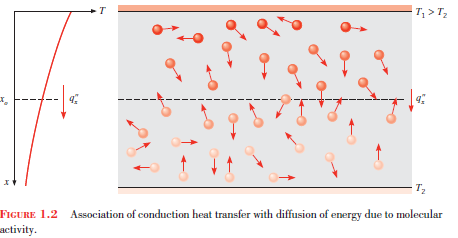

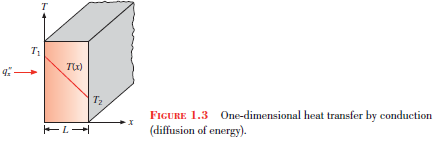

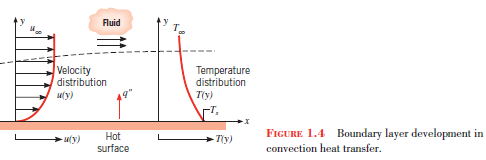

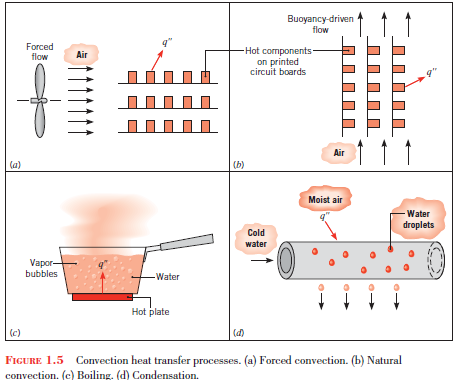

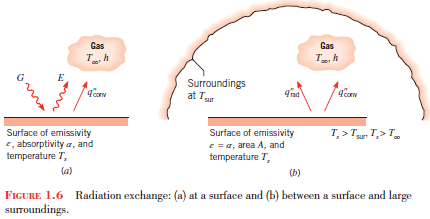

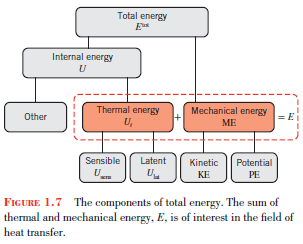

Eksempel 2.3

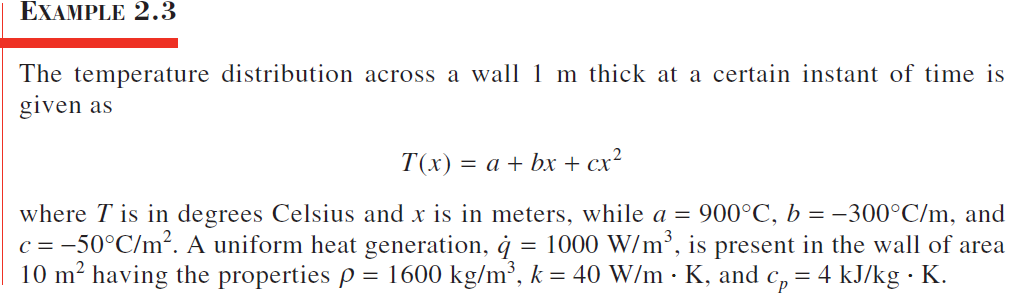

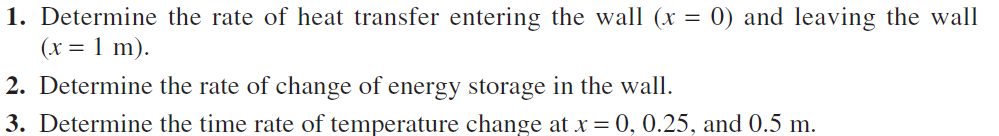

syms x
a = 900;
b = -300;
c = -50;
q_t = 1000; %W/m^3
A = 10; %m^2
rho = 1600; % kg/m^3
k = 40; %W/m * K
c_p = 4; % kJ/kg * K

T = a + b*x + c*x^2 

dTdt = diff(T)
dTdt_num =matlabFunction(dTdt)
% dTdt_num(0)
% dTdt_num(1)

q_in = -k*A*dTdt %fouires formel

q_left = subs(q_in, x,0)
q_right = subs(q_in, x,1)


2 - opstiller energi balance

E_in = q_left;
E_out = q_right;
E_g = q_t * A * 1;

E_st = E_in + E_g - E_out 